# **Relatório do Laboratório de Sinais e Sistemas**

**Q1.1**

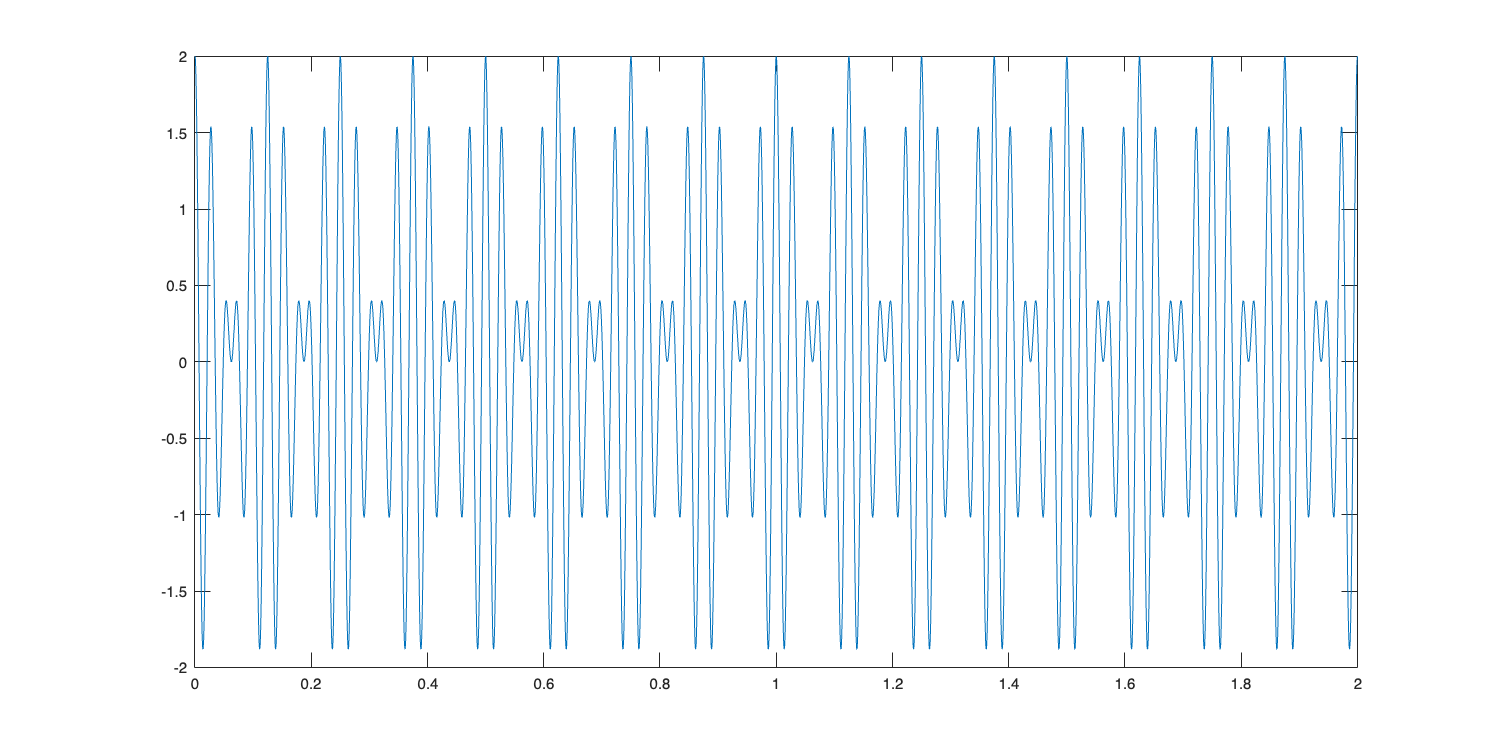

samplerateQ1 = 16e3; % Hz
t = (0:1/samplerateQ1:2); % s
f1 = 32; % Hz
f2 = 40; % Hz
x = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
plot(t,x)

%[xi, yi] = ginput;
%period = mean(diff(xi))

Teoricamente, o período fundamental do sinal é o menor múltiplo comum (MMC) dos períodos fundamentais de cada cosseno.

Ao trabalhar com números racionais (como os períodos fundamentais de cada cosseno, que são o inverso das suas frequências), temos:


$$\text{MMC} = \frac{\text{MMC dos numeradores (= 1)}}{\text{MDC dos denominadores}}$$


function mmc = LCM(a,b)
    [num_a, den_a] = rat(a)
    [num_b, den_b] = rat(b)
    mmc = (lcm(num_a, num_b))/(gcd(den_a, den_b))
end
theoretical_period = LCM(1/f1, 1/f2)

num_a = 1

den_a = 32

num_b = 1

den_b = 40

mmc = 0.1250

theoretical_period = 0.1250

O período que medimos, como a média das diferenças subsequentes entre "localizações periódicas" no sinal, concorda com o período teórico que calculámos acima.

% "Localizações Periódicas" é muito mau ahhahah tenho de mudar

**Q1.2**

period_in_samples = LCM(theoretical_period, 1/samplerateQ1) * samplerateQ1

num_a = 1

den_a = 8

num_b = 1

den_b = 16000

mmc = 0.1250

period_in_samples = 2000

Direct measurement:

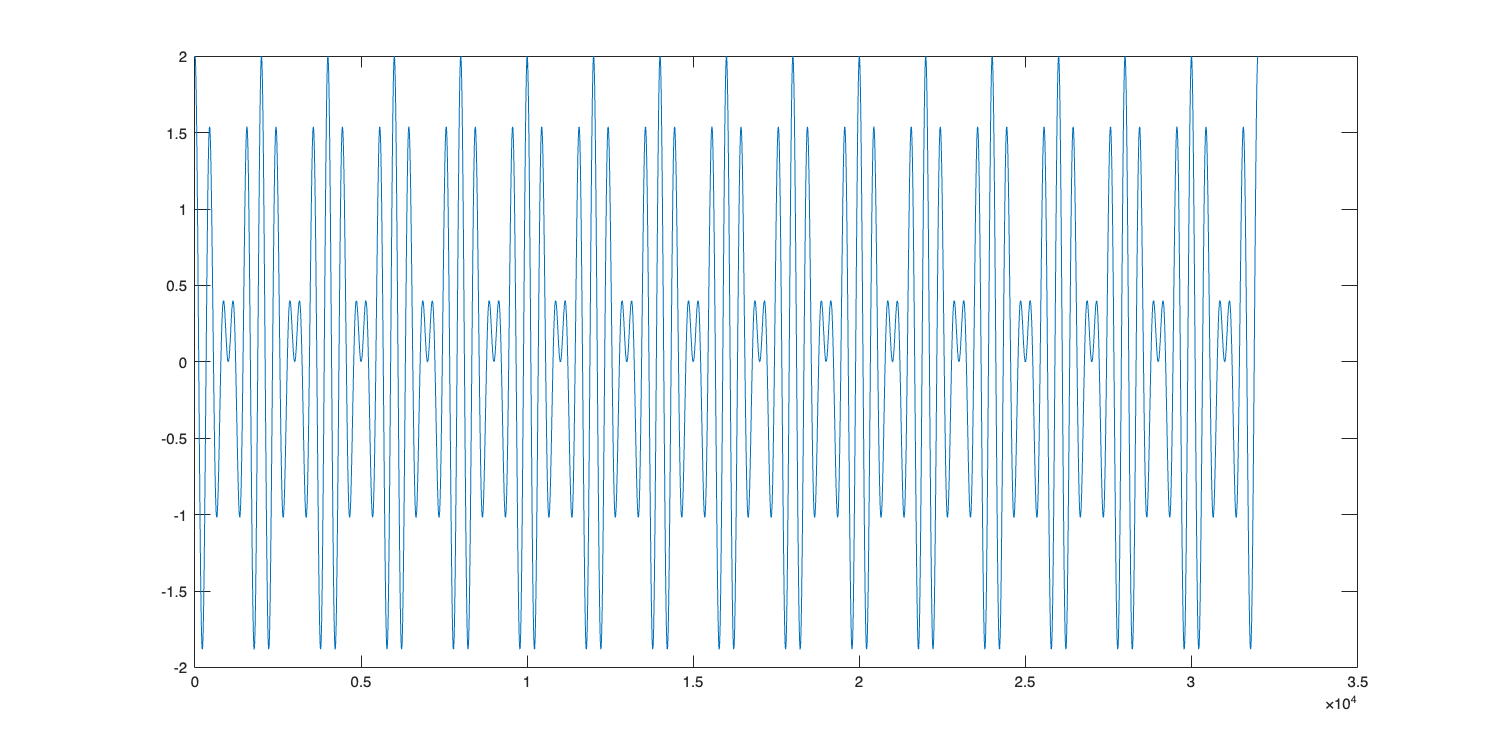

plot(x)

%meter foto com os pontos

y = downsample(x,3);
period_in_samples_y = LCM(theoretical_period, 1/(samplerateQ1/3))*samplerateQ1/3

num_a = 1

den_a = 8

num_b = 3

den_b = 16000

mmc = 0.3750

period_in_samples_y = 2000

Why does this only seemingly disagree with direct measurement from `plot(y)`?

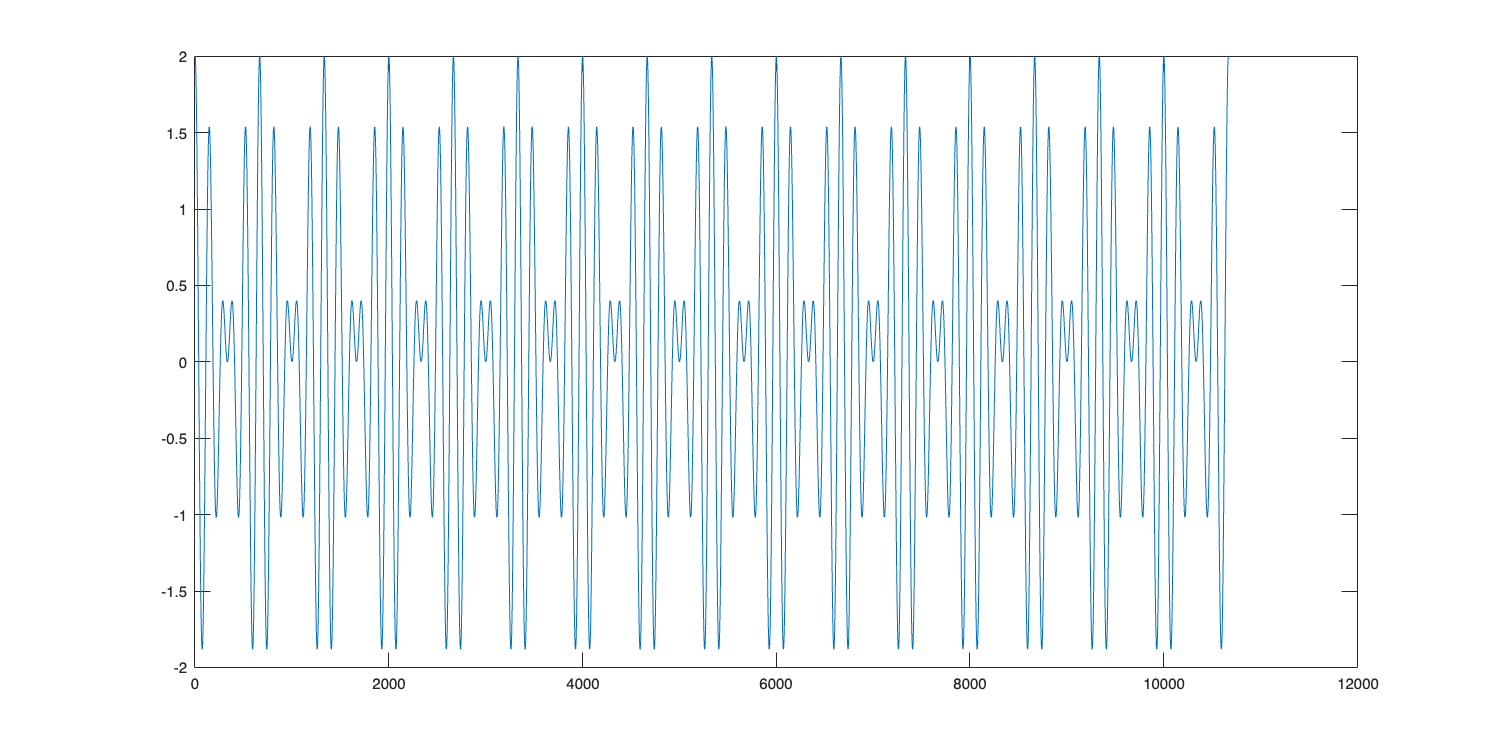

plot(y);

%[xxx,yyy] = ginput;
%measured_period_samples_y = diff(xxx)
% Cenas a mencionar:
% 1) fator pelo qual diminuimos sampling rate = fator pelo qual aumentamos
% período, no tempo MAS como # de samples/tempo também diminui pelo mesmo
% fator,  (T' = 3T MAS n'/T' = (1/3) *n/T
% 2) cena sobre o ponto não apanhar ali mm o pico
% meter foto com os pontos

Teoricamente diferem por causa do domínio, o medido terá que ser um inteiro

**Q1.3**

A4 = 440; % Hz
function frequency = noteFrequencyFromHalfsteps(no_halfsteps)
    A4 = 440; % Hz
    ratio = 2^(1/12);    
    frequency = A4 * ratio^no_halfsteps;
end

C4 = noteFrequencyFromHalfsteps(-9);
E4 = noteFrequencyFromHalfsteps(-5);
Fs4 = noteFrequencyFromHalfsteps(-3);
G4 = noteFrequencyFromHalfsteps(-2);
B4 = noteFrequencyFromHalfsteps(2);
F4 = noteFrequencyFromHalfsteps(-4);

Use the `seqsin` function to generate a sequence of sinusoids and silence gaps. Create x as the following sequence and listen to the resulting signal:


$$\text{R(0.7), E4(0.25), E4(0.25), F4(0.25), F\#4(0.5), A4(0.25),} \\

\text{F\#4(0.25), A4(0.25), F\#4(0.25), F\#4(0.25), F4(0.25),} \\

\text{E4(0.25), B4(0.25), E4(0.25), E4(0.5), R(0.7)}$$


noteSeq = seqsin(samplerateQ1, 0, 0.7, E4, 0.25, E4, 0.25, F4, 0.25, Fs4, 0.5, A4, 0.25, ...
            Fs4, 0.25, A4, 0.25, Fs4, 0.25, Fs4, 0.25, F4, 0.25, ...
            E4, 0.25, B4, 0.25, E4, 0.25, E4, 0.5, 0, 0.7);
soundsc(noteSeq, samplerateQ1)

**Q1.4**

samplerate=16e3

samplerate = 16000

u = @(t) (t >= 0);
t = (-4:1/samplerate:4);

O valor do degrau unitário muda em t=0, assim, para u(at+b) obtêm-se o valor para a mudança de t=-b/a.

se a<0 u(at+b) = u(-t-t0), 

se a>0 u(at+b) = u(t-to)

a=rand

a = 0.8147

b=rand

b = 0.9058

t0=-b/abs(a)

t0 = -1.1118

sinal_a = sign(a)

sinal_a = 1

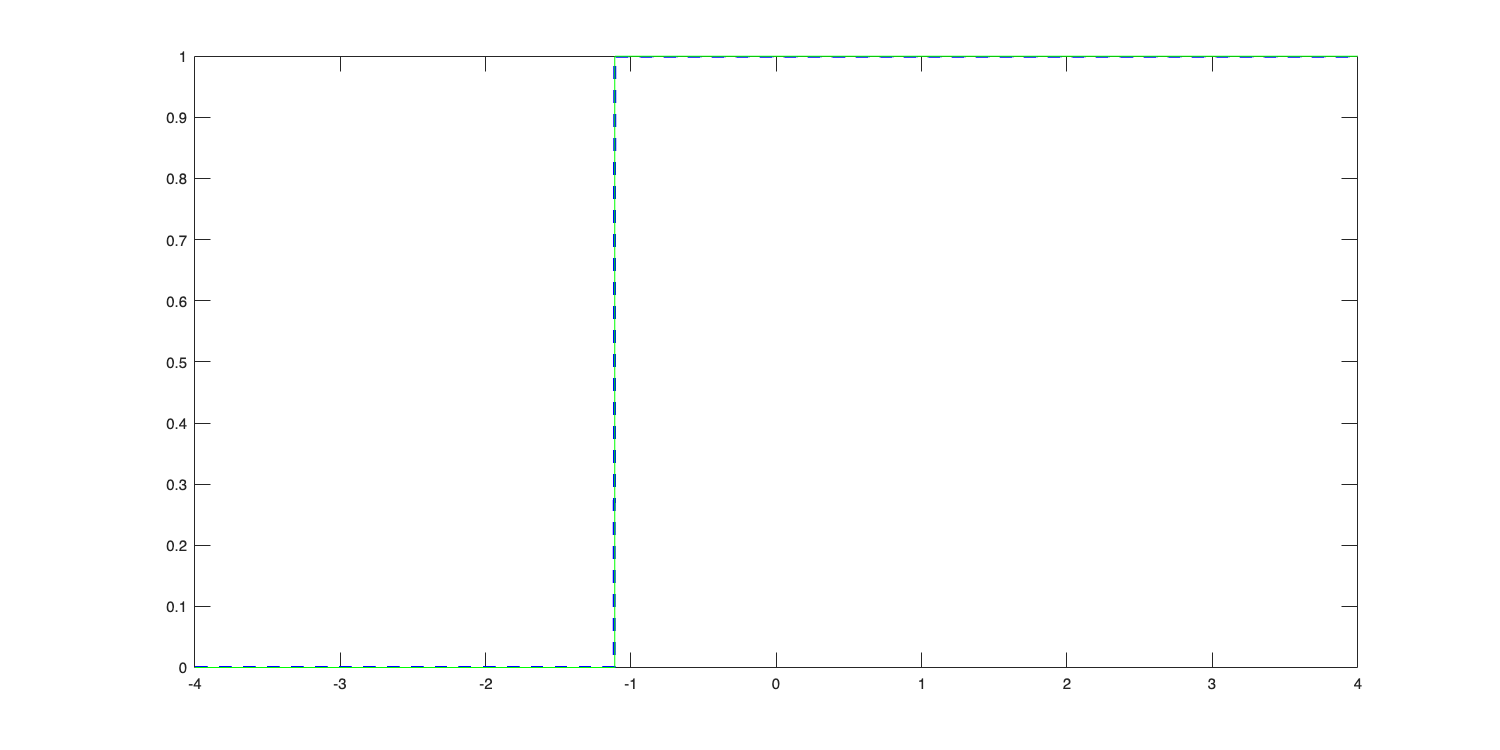

plot(t,u(a*t+b),'b--', 'LineWidth', 2); hold on
plot(t, u(sinal_a*t-t0),"g"); hold off

% relatório por varios lado a lado

s = @(t) (t >= 0).*t;                   % Unit ramp
uD = @(t,D) (1/D)*(s(t+D/2)-s(t-D/2));  % Approximate unit step
duD = @(t,D,h) (uD(t+h/2,D)-uD(t-h/2,D))/h; % Numeric derivative
deltaD = @(t,D) duD(t,D,1e-6);          % Approximate unit impulse

O sinal tem valores diferentes de zero entre t0-D/2 e t0+D/2:

D = rand

D = 0.1270

T = D/2 

T = 0.0635

t00 = rand

t00 = 0.9134

%dt para aumentar a resolução, aka + data points do que o default 1 em 1
dt=D/1000

dt = 1.2699e-04

t2 = t00-T-D*1000:dt:t00+T+D*1000

t2 =  -126.1369 -126.1368 -126.1367 -126.1366 -126.1364 -126.1363 -126.1362 -126.1360 -126.1359 -126.1358 -126.1357 -126.1355 -126.1354 -126.1353 -126.1352 -126.1350 -126.1349 -126.1348 -126.1346 -126.1345 -126.1344 -126.1343 -126.1341 -126.1340 -126.1339 -126.1338 -126.1336 -126.1335 -126.1334 -126.1333 -126.1331 -126.1330 -126.1329 -126.1327 -126.1326 -126.1325 -126.1324 -126.1322 -126.1321 -126.1320 -126.1319 -126.1317 -126.1316 -126.1315 -126.1313 -126.1312 -126.1311 -126.1310 -126.1308 -126.1307


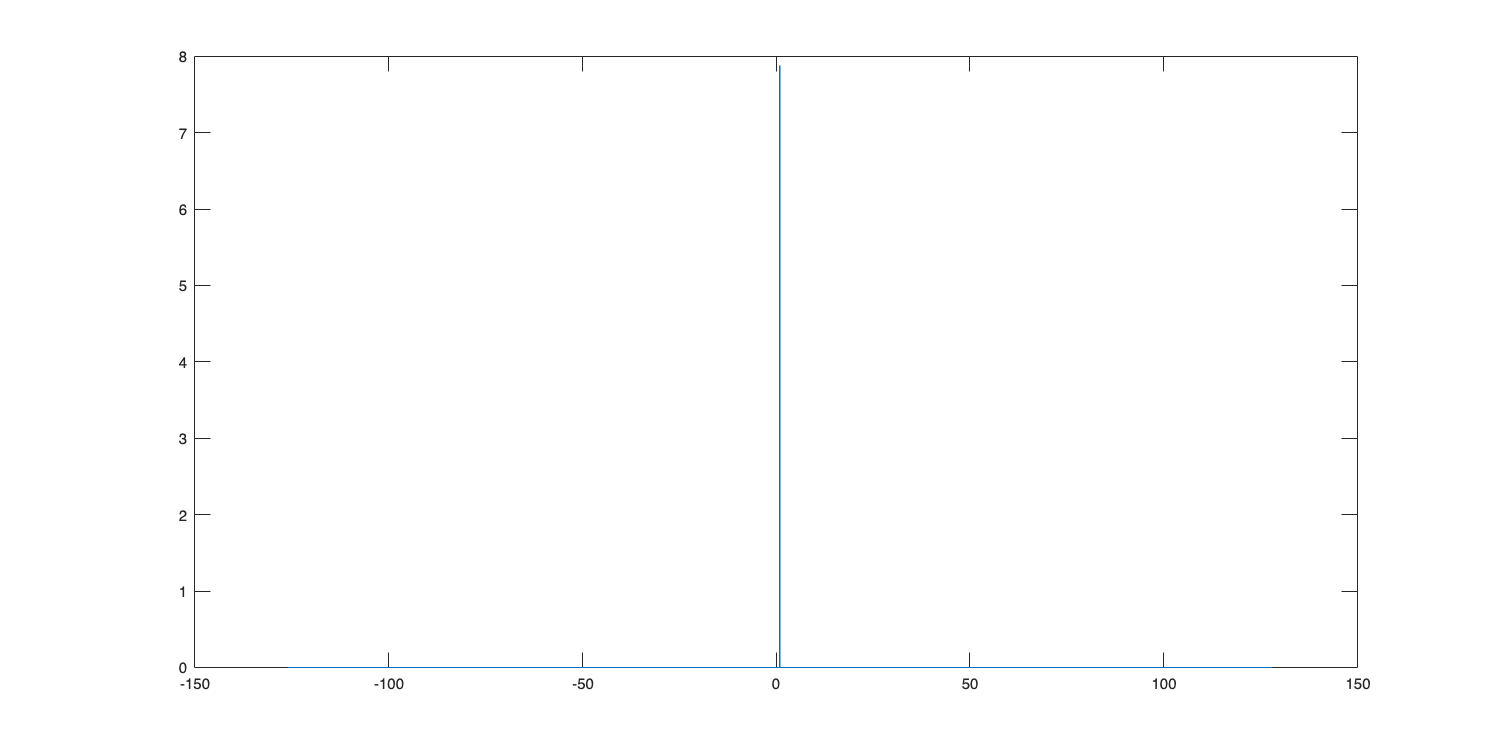

plot(t2, deltaD(t2-t00,D)); hold off

% meter -0.5 a 1.5 no yy

a = 0.5

a = 0.5000

t3 = (-5:0.001:5)

t3 =    -5.0000   -4.9990   -4.9980   -4.9970   -4.9960   -4.9950   -4.9940   -4.9930   -4.9920   -4.9910   -4.9900   -4.9890   -4.9880   -4.9870   -4.9860   -4.9850   -4.9840   -4.9830   -4.9820   -4.9810   -4.9800   -4.9790   -4.9780   -4.9770   -4.9760   -4.9750   -4.9740   -4.9730   -4.9720   -4.9710   -4.9700   -4.9690   -4.9680   -4.9670   -4.9660   -4.9650   -4.9640   -4.9630   -4.9620   -4.9610   -4.9600   -4.9590   -4.9580   -4.9570   -4.9560   -4.9550   -4.9540   -4.9530   -4.9520   -4.9510


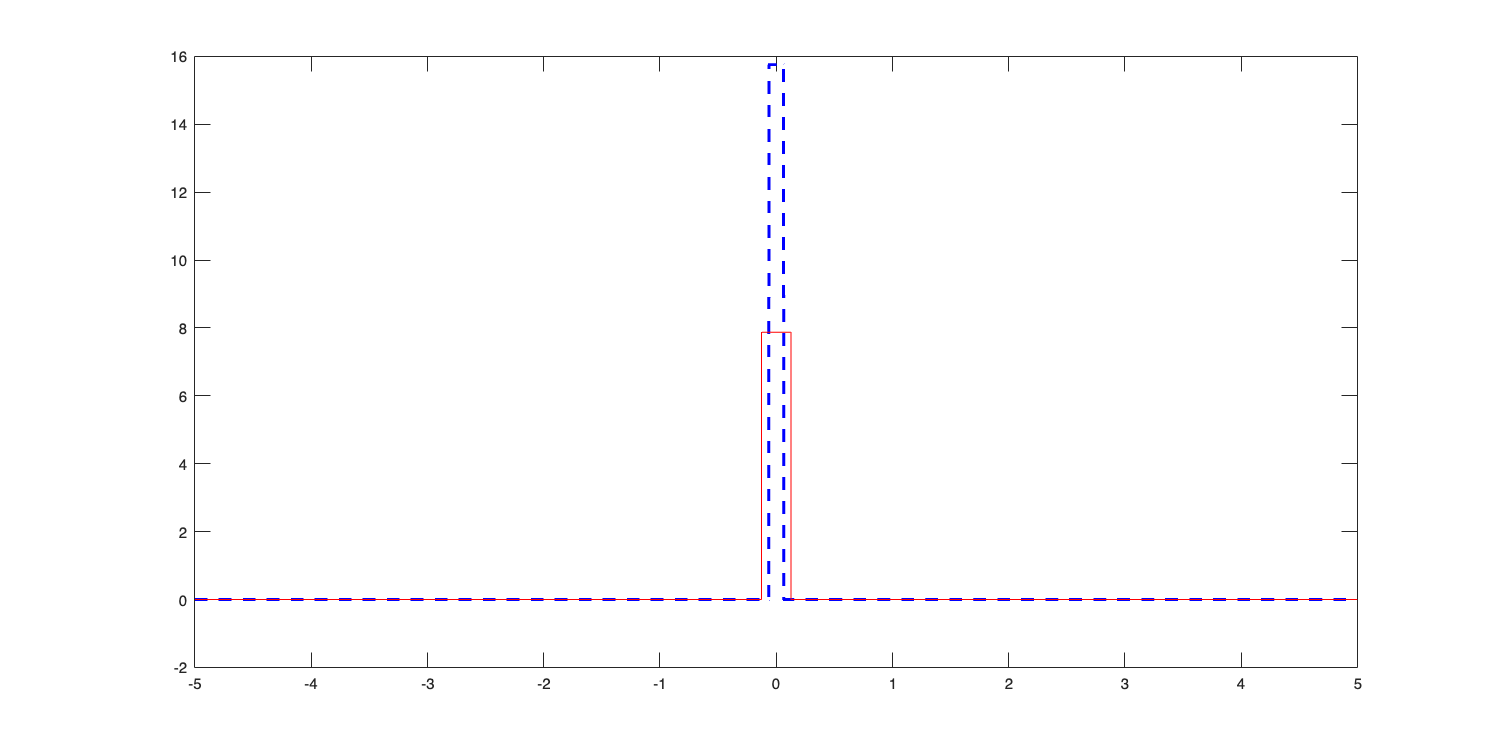

deltaA = deltaD(t3, D)/abs(a);
plot(t3, deltaA, "b--", "LineWidth",2); hold on
plot(t3, deltaD(a*t3, D), "r"); hold on

**Q2.1**

system1 = @(x) filter([1 zeros(1,round(0.4*samplerateQ1) - 1) 0.7],1,x);
[x,samplerateQ2] = audioread('echoin.wav');

soundsc([x; system1(x)], samplerateQ2); 

% Em vez de só ouvir o sinal transformado, ouvimos o sinal de entrada 
% antes do sinal de saída - [entrada; saída] -, para poder comparar os dois.

Ao ouvir o resultado da aplicação do sinal lido do ficheiro `echoin.wav` ao sistema `system1`, conseguimos isolar o sinal original, no entanto, ouvimo-lo repetido pouco depois, como que um eco, menos intenso.

Perante o sistema definido, isto faz todo o sentido. Analisemos porquê.

O sistema sobrepõe 2 sinais: o sinal de entrada e uma transformação do sinal de entrada pesado por uma constante. Nesta última parcela, ao usar uma constante $<1$, o sinal é atenuado e, com uma transformação na variável independente, é ainda atrasado. Estes dois fenómenos faz com que, ao sinal de entrada, estejamos a somar algo que simule o seu eco.

**Q2.2**

A figura parece representar uma sobreposição de inúmeros impulsos com diferentes atrasos, que diminuem progressivamente  ($\sum\limits_i a_i \cdot\delta(t-t_{0_i})$), com $a_{i+1}$ aproximadamente menor que $a_i$). 

Por isto, observamos menos impulsos mais fortes para atrasos pequenos, e mais impulsos mais fracos para atrasos maiores.

Este padrão ocorre devido ao comportamento físico do sinal numa sala como a descrita. Ao ser emitido pela fonte, o sinal reflete-se nas paredes, onde é parcialmente absorvido e atenuado a cada reflexão. Assim, o sinal muda de direção e perde intensidade ao longo do tempo. Quanto mais reflexões o sinal sofre, maior distância percorre e, consequentemente, maior é o atraso antes de atingir o recetor.

Inicialmente, para atrasos pequenos, há menos impulsos porque o sinal segue caminhos diretos e curtos até ao recetor. Estes caminhos envolvem menos reflexões, resultando em menor atenuação. Com o passar do tempo, as frentes de onda que seguiram caminhos mais indiretos, sofrendo múltiplas reflexões, começam a chegar ao recetor. Estes sinais percorreram distâncias maiores e foram mais atenuados, o que resulta em impulsos mais fracos com atrasos maiores. São mais impulsos pois há muitas direções diferente das "ótimas", que levam aos caminhos mais curtos.

Assim, a resposta ao impulso reflete a distribuição das trajetórias que o sinal percorre.

% posição 3d do receiver
mic = [1 2 1];
n = 12;
% refletividade das paredes
r = 0.7;
% dimensões da sala
rm = [10 10 3];
% posição 3D da source
src = [5 5 1];
h = rir(samplerate, mic, n, r, rm, src);

[x,samplerate] = audioread('echoin.wav');
y = conv(h,x);
% soundsc(y,samplerate)

**Q2.3**

load fingerprint.mat

soundsc(x, samplerate); % input original x
pause(length(x) / samplerate); % tempo de espera entre a reprodução dos sons
soundsc(y, samplerate); % output original y
disp("original") 

original


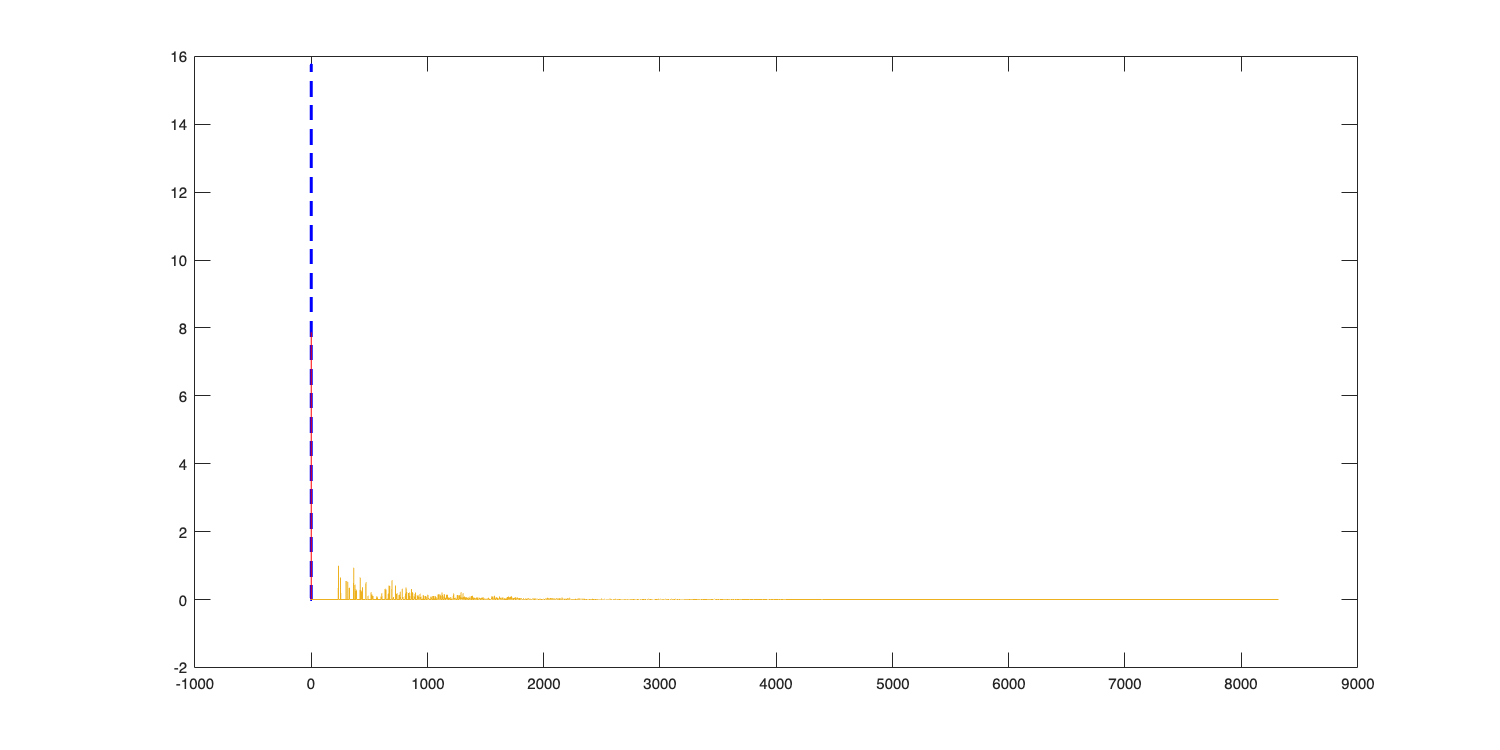

plot(h); hold off


rm_now = [20 15 10];
r_wood = 0.6;
r_conc = 0.9;
% não tenho a certeza do y, estou a assumir que é igual à do receiver no protocolo diz: 
% The source is located at the same height of the receiver (1 m), but its horizontal coordinates are unknown
src_3 = [4 2 1];
src_10 = [11 2 1];

% hipóteses: 
% paredes de madeira, fonte à distância de 3m do recetor
h_wood_3 = rir(samplerate, mic, n, r_wood, rm_now, src_3);
y_wood_3 = conv(h_wood_3, x);
soundsc(y_wood_3, samplerate);
disp("wood3") 

wood3


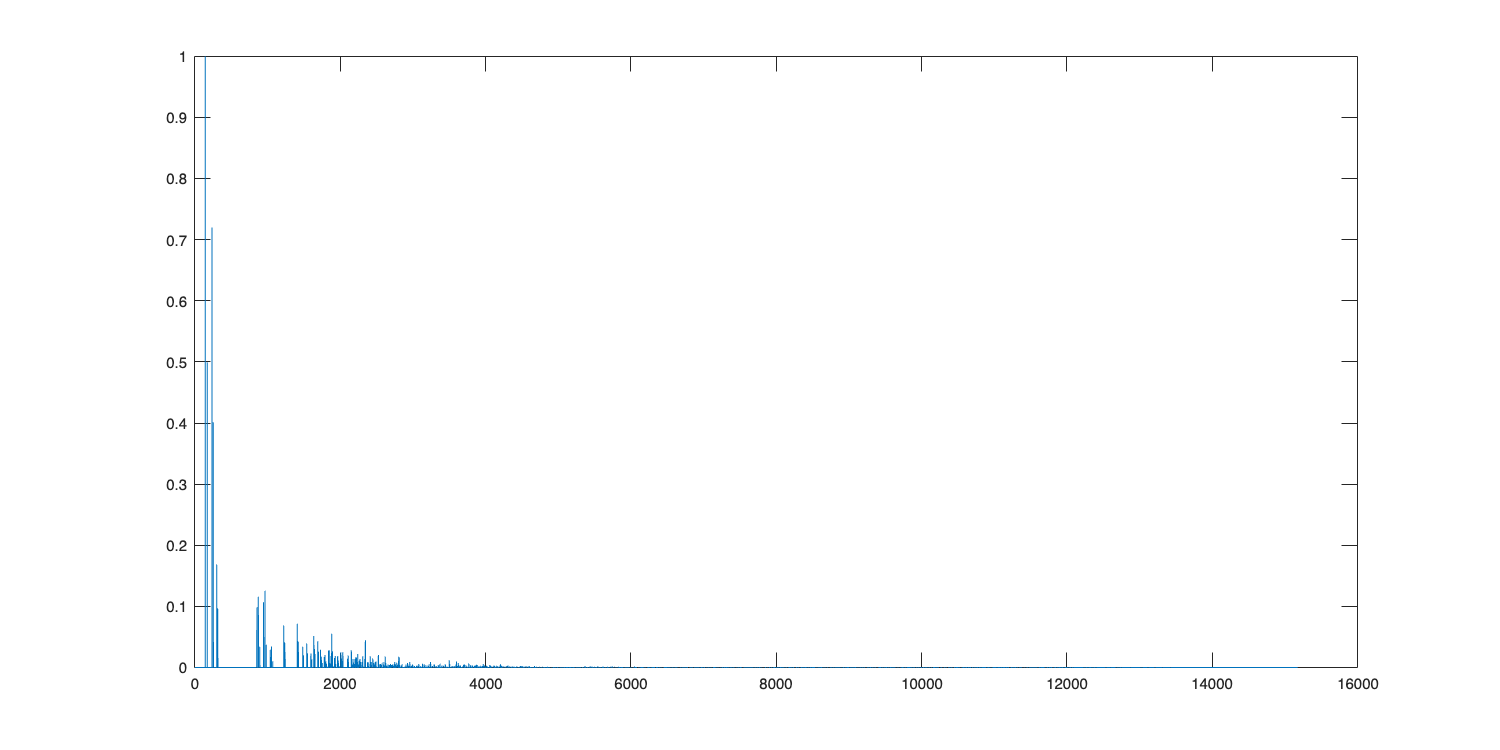

pause(length(y_wood_3) / samplerate);

plot(h_wood_3); hold off


% paredes de madeira, fonte à distância de 10m do recetor
h_wood_10 = rir(samplerate, mic, n, r_wood, rm_now, src_10);
y_wood_10 = conv(h_wood_10, x);
soundsc(y_wood_10, samplerate);
pause(length(y_wood_10) / samplerate);
disp("wood10") 

wood10


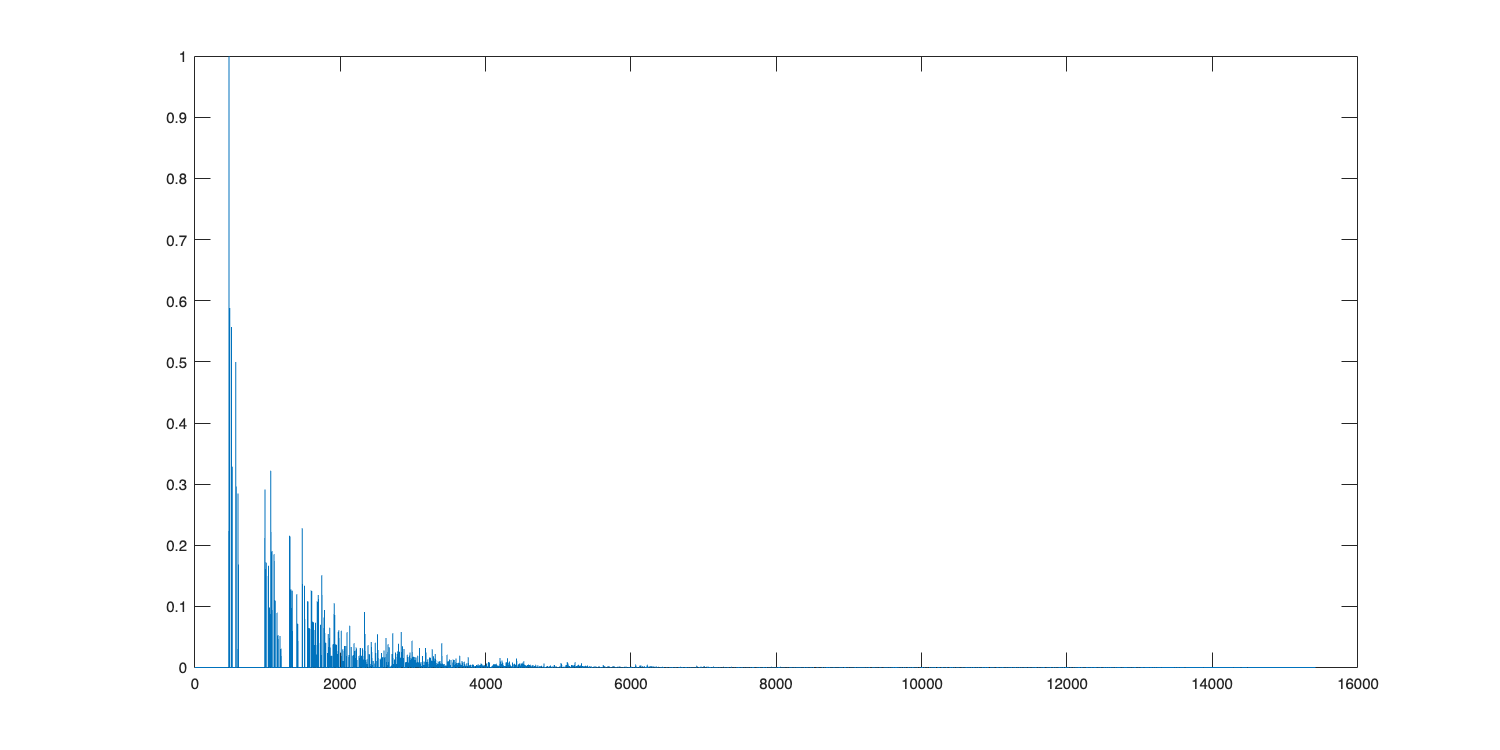

plot(h_wood_10); hold off


% paredes de betão, fonte à distância de 3m do recetor
h_conc_3 = rir(samplerate, mic, n, r_conc, rm_now, src_3);
y_conc_3 = conv(h_conc_3, x);
soundsc(y_conc_3, samplerate);
pause(length(y_conc_3) / samplerate);
disp("conc3") 

conc3


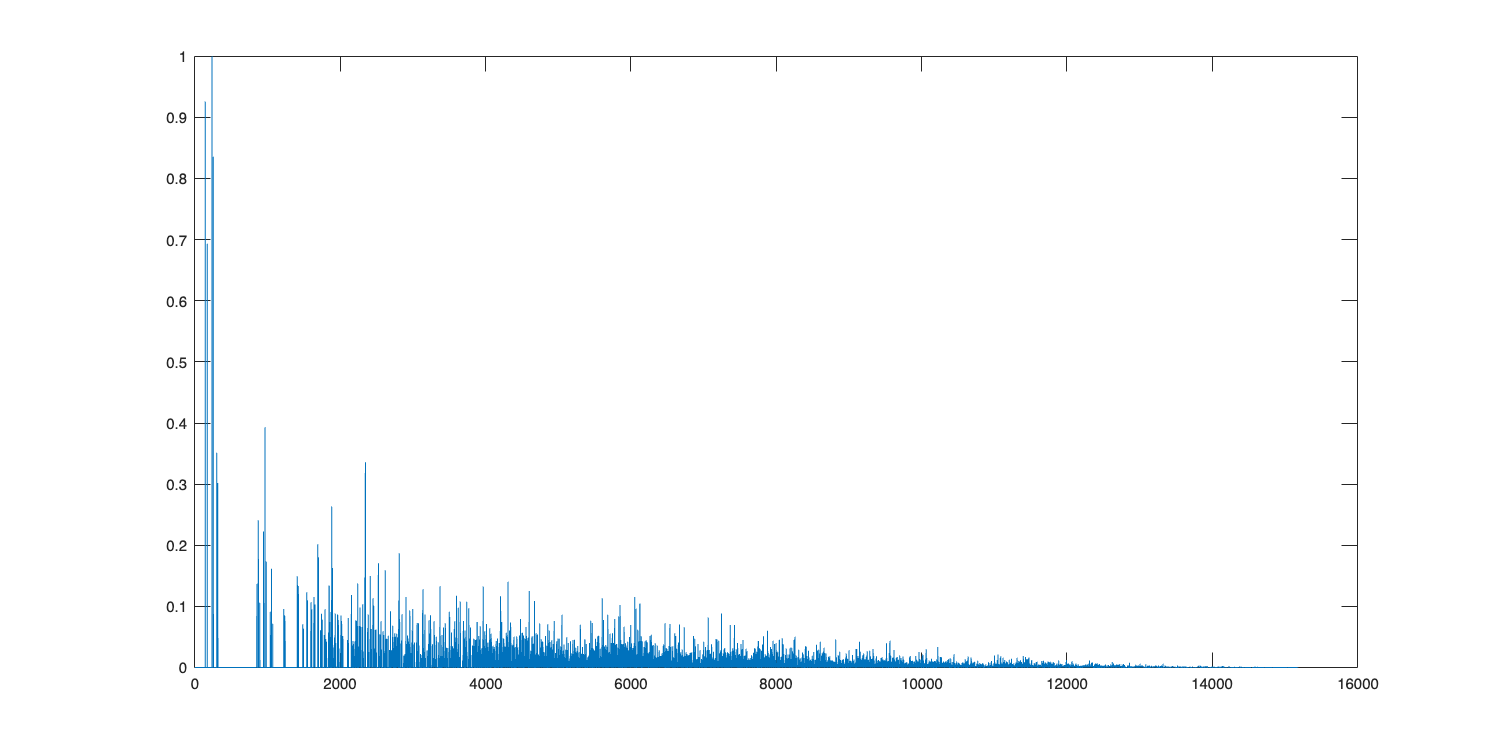

plot(h_conc_3); hold off


% paredes de betão, fonte à distância de 10m do recetor
h_conc_10 = rir(samplerate, mic, n, r_conc, rm_now, src_10);
y_conc_10 = conv(h_conc_10, x);
soundsc(y_conc_10, samplerate);
pause(length(y_conc_10) / samplerate);
disp("conc10") 

conc10


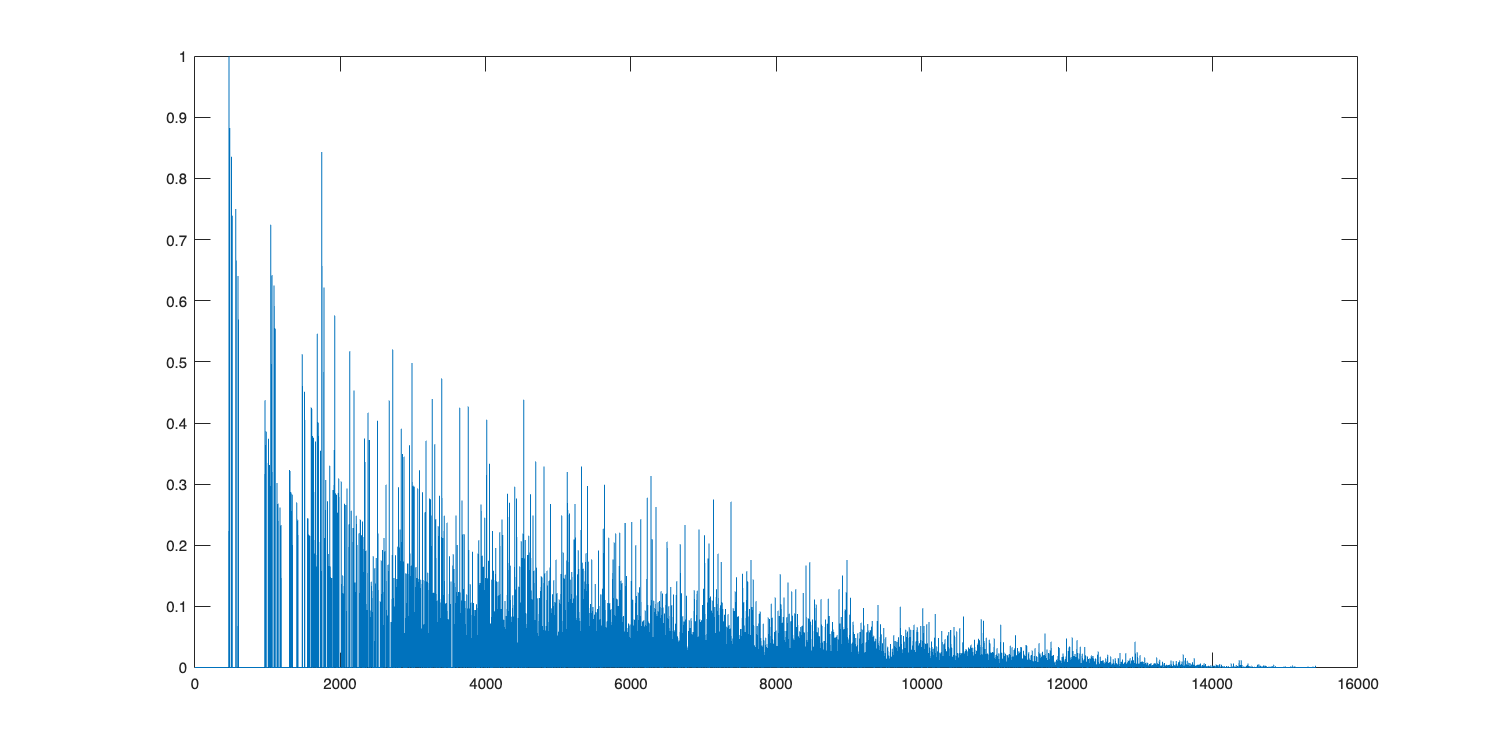

plot(h_conc_10); hold off


% escrever melhor

De acordo com as simulações o mais provável é que as paredes sejam de madeira e a fonte esteja a uma distância de 10m do recetor. Os plots são também mais parecidos.

**Q2.4**

system1 = @(x) filter([1 zeros(1,round(0.4*samplerate) - 1) 0.7],1,x);
samplerate = 16e3;
t = (-4:1/samplerate:4);
omega = 27;
x1 = cos(omega*t);
y1 = system1(x1);
A = cos(10.8)+sin(10.8)+pi

A = 1.9663

phi = -10.8

phi = -10.8000

y_teorico= A*cos(27*t+phi)

y_teorico =     1.6442    1.6424    1.6405    1.6387    1.6369    1.6350    1.6332    1.6313    1.6295    1.6276    1.6258    1.6239    1.6220    1.6201    1.6183    1.6164    1.6145    1.6126    1.6107    1.6088    1.6069    1.6050    1.6030    1.6011    1.5992    1.5973    1.5953    1.5934    1.5914    1.5895    1.5875    1.5856    1.5836    1.5816    1.5796    1.5777    1.5757    1.5737    1.5717    1.5697    1.5677    1.5657    1.5637    1.5617    1.5597    1.5576    1.5556    1.5536    1.5515    1.5495


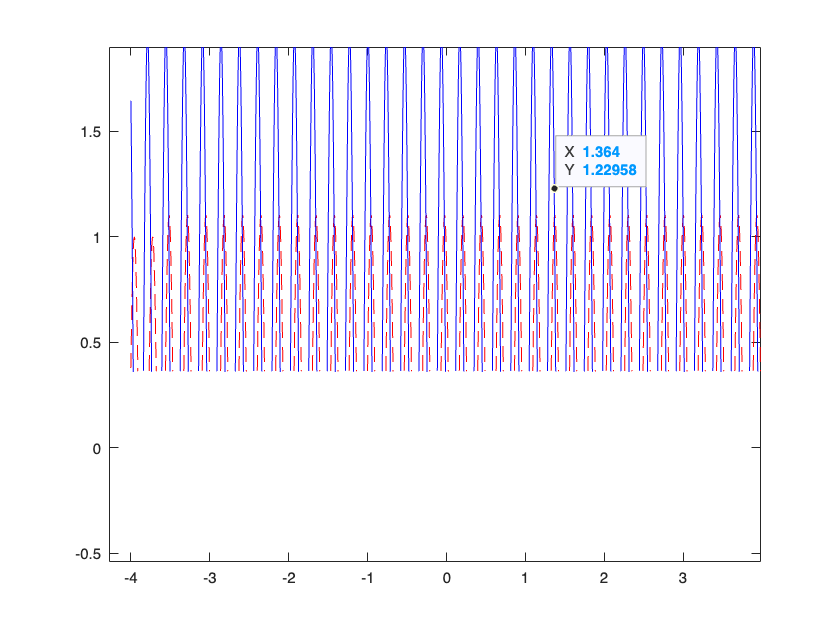

figure
plot(t, y1, "r--"); hold on
plot(t, y_teorico, "b"); hold off

%%

**Q2.5**

## Linearidade

S2(a(x1+x2)) (blue) vs a*S2(x1)+a*S2(x2) (green)


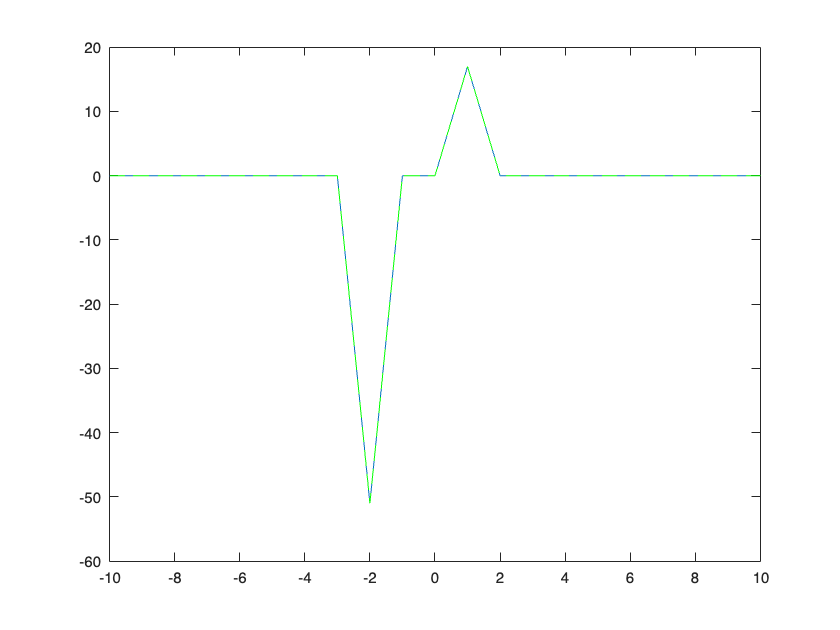

function test_linearity(t, x1,x2, a)
    s2_x1x2 = system2(a*(x1+x2),t);
    s2_x1_s2_x2 = a*system2(x1,t) + a*system2(x2,t);
    
    disp("S2(a(x1+x2)) (blue) vs a*S2(x1)+a*S2(x2) (green)")
    plot(t, s2_x1x2); hold on;
    plot(t, s2_x1_s2_x2, "g--"); hold off
end

t = -10:10;
x1 = deltaD(t-1,1);
x2 = -3*deltaD(t-2,1);
a=17;

test_linearity(t, x1, x2, a)


x1 = uD(t-4, 1);
x2 = -uD(t+1, 1);
a = 3

a = 3

S2(a(x1+x2)) (blue) vs a*S2(x1)+a*S2(x2) (green)


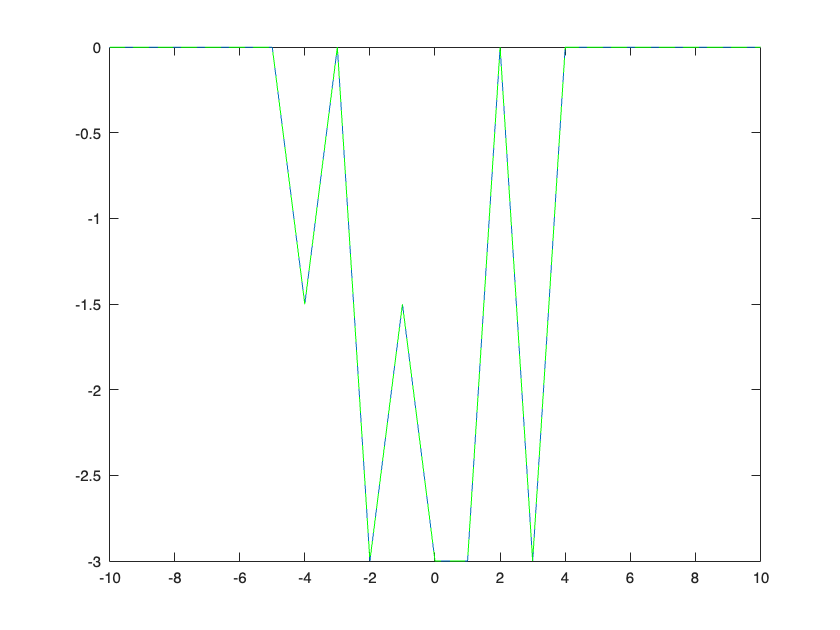


test_linearity(t, x1, x2, a)

t=-40:40

t =    -40   -39   -38   -37   -36   -35   -34   -33   -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9


S2(a(x1+x2)) (blue) vs a*S2(x1)+a*S2(x2) (green)


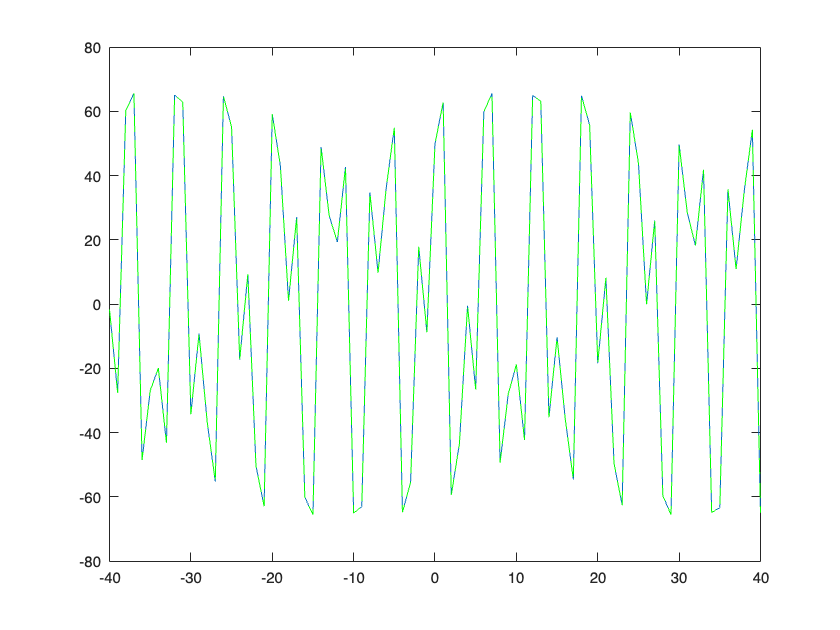

x1 = cos(t) + sin(t);
x2 = cos(t-1) + sin(t-5);
a = 20;
test_linearity(t, x1, x2, a)

Ao testar sinais fundamentais na construção de outros sinais, mas todos diferentes - um impulso, um degrau unitário e um $cos$, observámos sempre um comportamento linear. 

Computacionalmente, não nos é possível de testar o espaço todo de sinais de entrada - já que este é infinito. No entanto, uma vez que os sinais que nós testámos poderiam ser usados para construir qualquer sinal de entrada neste espaço de sinais, através de deslocamentos no tempo e combinações lineares, estamos bastante confiantes de que se trata de um sistema linear.

Há que reforçar que não podemos constatar com certeza a linearidade, só podemos comentar os exemplos que observámos. (Exemplo: se, para t=1000, o sistema não for linear, tal não estaria incluído nos nossos testes. Como não temos modo de criar uma suite de testes absolutamente exaustiva, não podemos generalizar a nossa conclusão.)

## Invâriancia no Tempo

function test_timeInvariance(t, t0, x)
    x_t = x(t);
    x_t_t0 = x(t-t0);
    y_t_t0 = system2(x_t, t);
    S2_x_t_t0 = system2(x_t_t0, t);

    font_s = 16;

    plot(t, S2_x_t_t0, "r"); hold on; plot(t+t0, y_t_t0, "b--"); hold off; 
    xlim([-10 10]); ylim([-0.2 1.2]);
    xlabel('t', 'FontSize', font_s, 'Interpreter', 'latex');
    ylabel('$S(x(t))$', 'FontSize', font_s, 'Interpreter', 'latex');
    title(['\fontsize{16} {\color{red}S(x(t-t0)) \color{black} vs \color{blue}y(t-t0)}'])
end

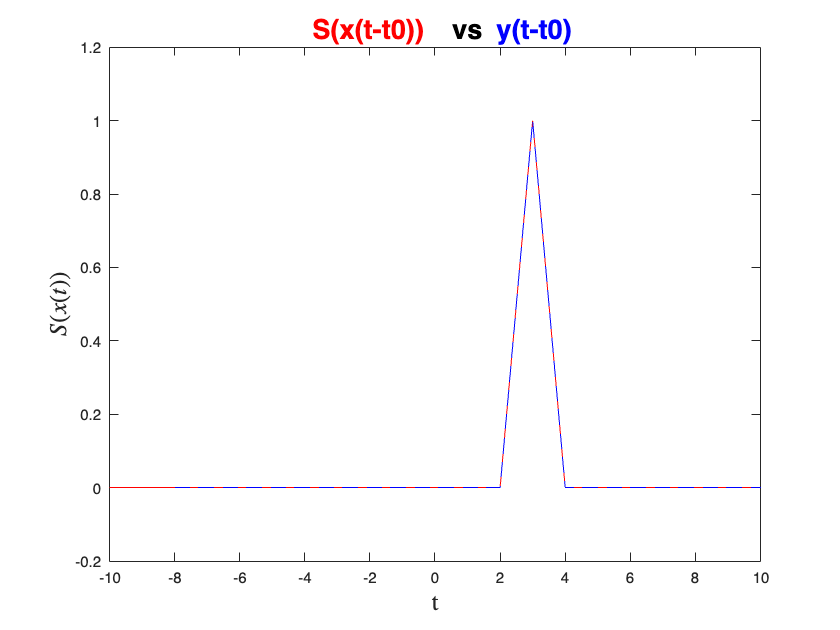

t = -10:10;
x1 = @(t) deltaD(t-1,1);

test_timeInvariance(t, 2, x1)

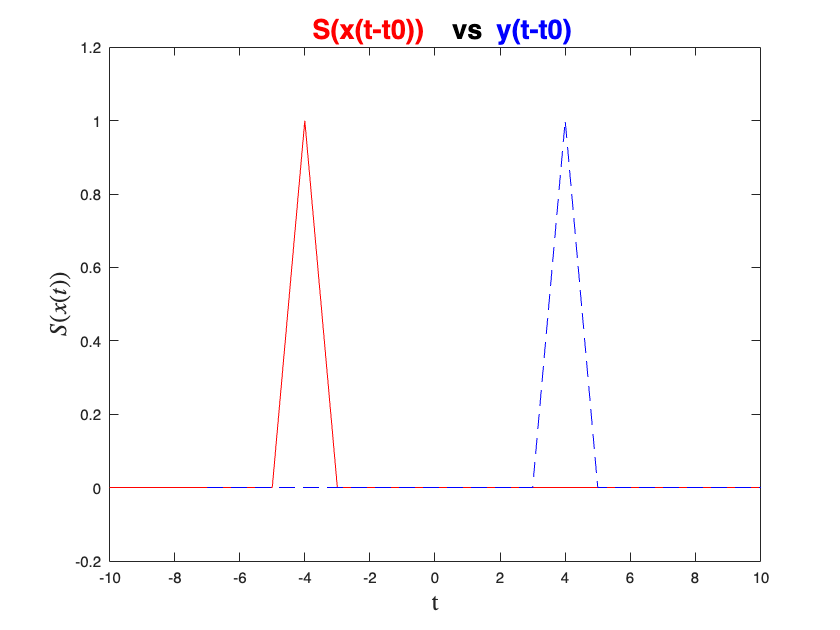

test_timeInvariance(t, 3, x1)

Com um exemplo, vemos que o sinal não é invariante no tempo.

Nestes gráficos, vemos a sobreposição de 2 casos.

Em vermelho, vemos o resultado da aplicação do `system2` num sinal `x` que foi deslocado no tempo. Em azul, vemos o resultado, deslocado no tempo, da aplicação do `system2 num sinal x`.

No primeiro gráfico, o deslocamento no tempo é de 2 unidades, ao passo que, no segundo, é de 3. Como podemos ver, no segundo gráfico os sinais obtidos não são equivalentes, o que nos diz que o sistema não pode ser invariante no tempo - se pudesse, os sinais seriam iguais independentemente do deslocamento temporal.

## Memória e Causalidade

function test_memory_or_causality(t, x1, x2, t0)
    % Let x1 and x2 be 2 similar signals which we will evaluate at point t0.
    % In constructing them, we should make them essentially the same, but
    % different only at some point t1≠t0.
    % If the output signal at t0 changes, then the system has memory.

    S2_x1 = system2(x1, t);
    S2_x2 = system2(x2, t);
    
    font_s = 16;

    figure;
    plot(t, x1, "r"); hold on; plot(t, x2, "g--"); xline(t0, 'k--', 'LineWidth', 1.5); hold off;
    xlim([-10 10]); ylim([-1.5 1.5]);
    xlabel('t','FontSize',font_s, 'Interpreter','latex'); ylabel('$x(t)$', 'FontSize',font_s, 'Interpreter','latex');
    title("Input signals: $\texttt{x1}$ in red, $\texttt{x2}$ in green", 'Interpreter','latex', 'FontSize', font_s);    
    

    figure;
    plot(t, S2_x1, "r"); hold on; plot(t, S2_x2, "g--"); xline(t0, 'k--', 'LineWidth', 1.5); hold off;
    xlim([-10 10]); ylim([-1.5 1.5]);
    xlabel('t','FontSize',font_s, 'Interpreter','latex'); ylabel('$S(x(t))$', 'FontSize',font_s, 'Interpreter','latex');
    title("Output signals: $S(\texttt{x1})$ in red, $S(\texttt{x2})$ in green", 'Interpreter','latex', 'FontSize', font_s);    

end


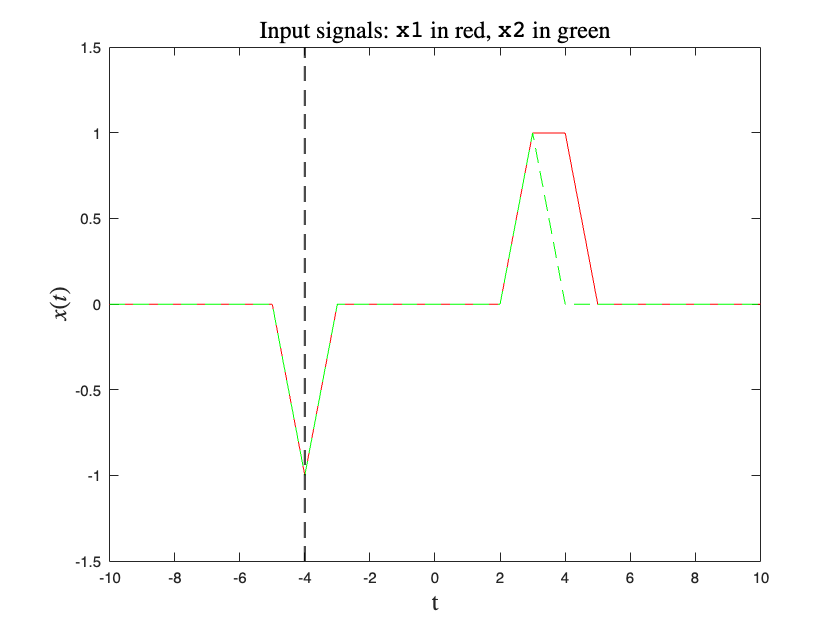

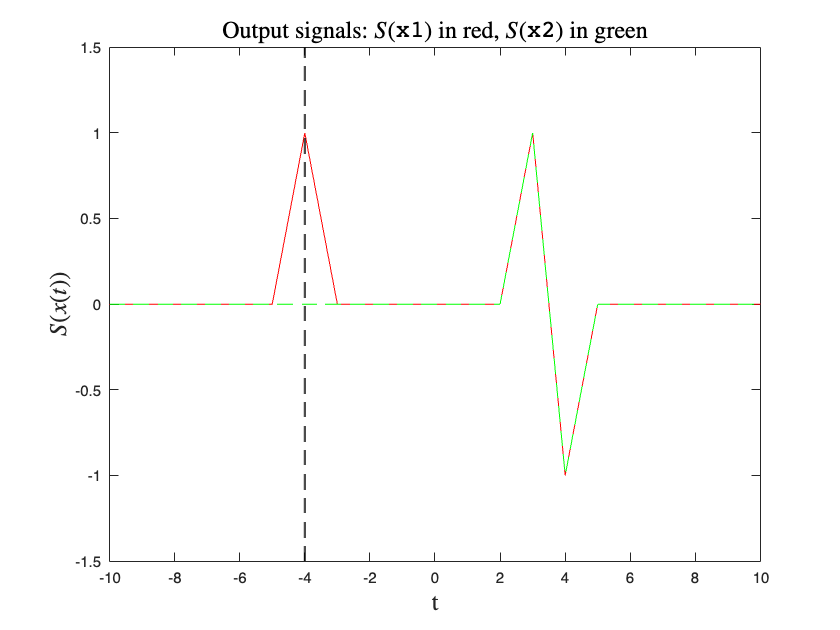

x1 = deltaD(t-4,1) + deltaD(t-3,1) - deltaD(t+4,1);
x2 = deltaD(t-3,1) - deltaD(t+4,1);
t0 = -4;

test_memory_or_causality(t, x1, x2, t0)

Por contra-exemplo, demonstramos que o sistema tem memória, e que não é causal: ao alterarmos o sinal de entrada num ponto t1=4 diferente do ponto t0=-4, e inclusive após deste, a saída do sistema altera-se nesse ponto t0=4, ou seja, a saída num ponto no tempo depende da entrada noutro ponto no tempo - cumprindo a definição de memória de um sistema -, ponto este que é posterior no tempo ao inicial - violando a definição de causalidade de um sistema.

## Estabilidade

## Invertibilidade

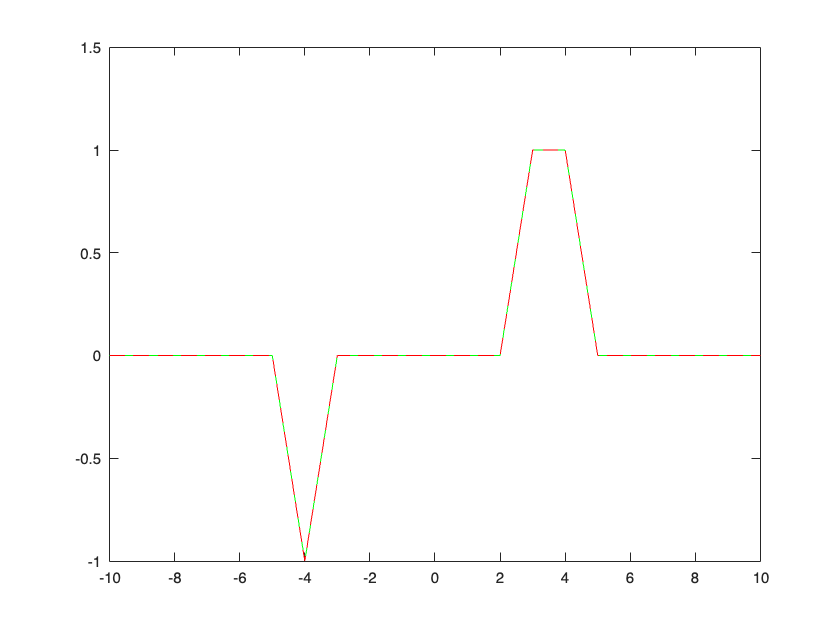

plot(t, system2(system2(x1, t), t), "g-"); hold on; plot(t, x1, "r--"); hold off;

**Q3.1**

samplerate = 16e3;
t = (-320:320)'/samplerate;
w0 = 2*pi*100;
T = 2*pi/w0;
disp(T/4)

    0.0025



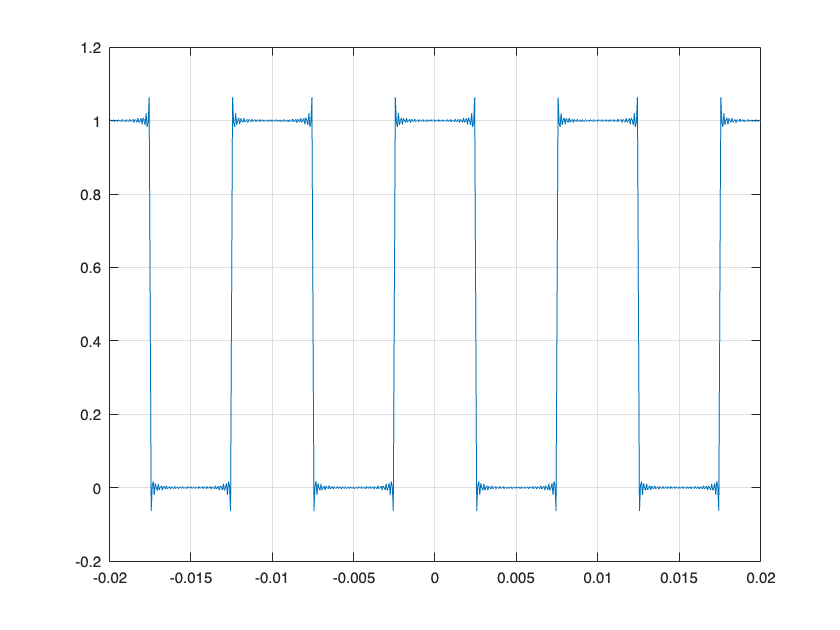

% SFC sem o deslocamento temporal de T1
ak = @(k) sin(k*w0*T/4)./(k*pi);
a0 = 1/2;   % Segregate a0, which often has a different expression
N = 100;    % Order of the Fourier expansion
xN = exp(1i*w0*t*(-N:N))*[ak(-N:-1) a0 ak(1:N)].';
figure;
plot(t,real(xN)); grid

Os detalhes da forma do sinal demonstram que a SFC é convergente pois verifica-se que é absolutamente integrável tem um número finito de máximos e mínimos num período e um número finito de descontinuidades num intervalo de tempo finito 

NÃO SEI SE É BEM ISTO QUE SE OBSERVA??

PORQUÊ QUE a0=1/2?

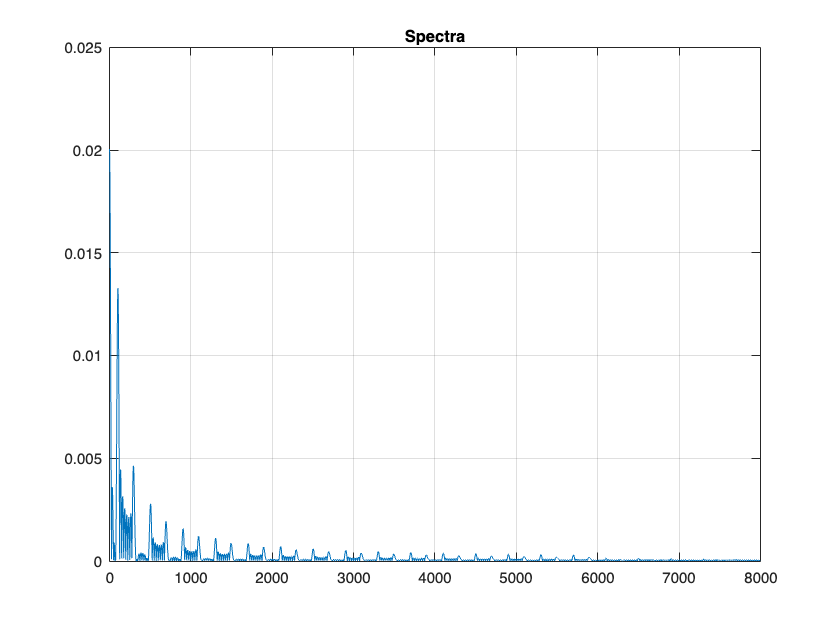

%spectra: representação do sinal no domínio da frequência
[XN, f] = cftransform(xN, find(t == 0), 1e4, samplerate);
figure;
% spectra
figure;
plot(f, abs(XN)); grid on
title('Spectra');

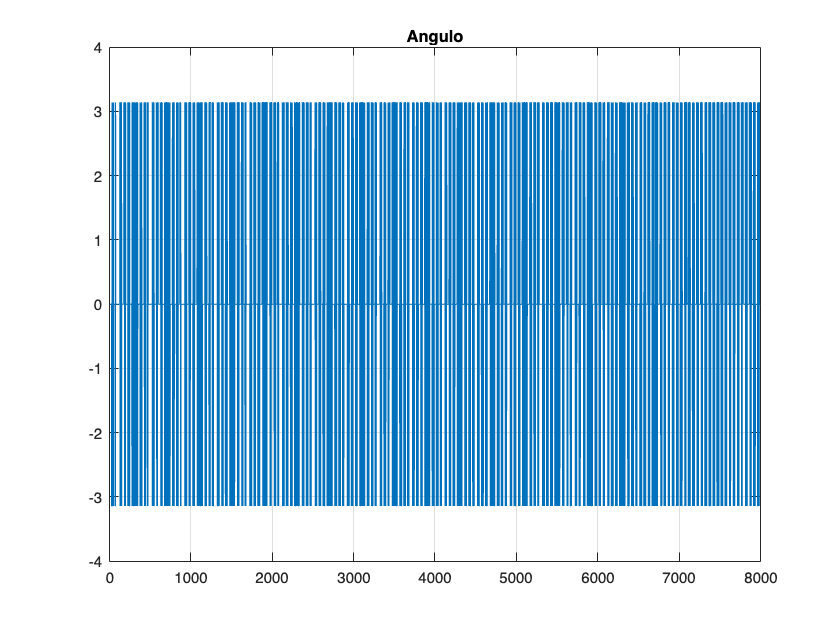


% angulo
figure;
plot(f, angle(XN)); grid on
title('Angulo')

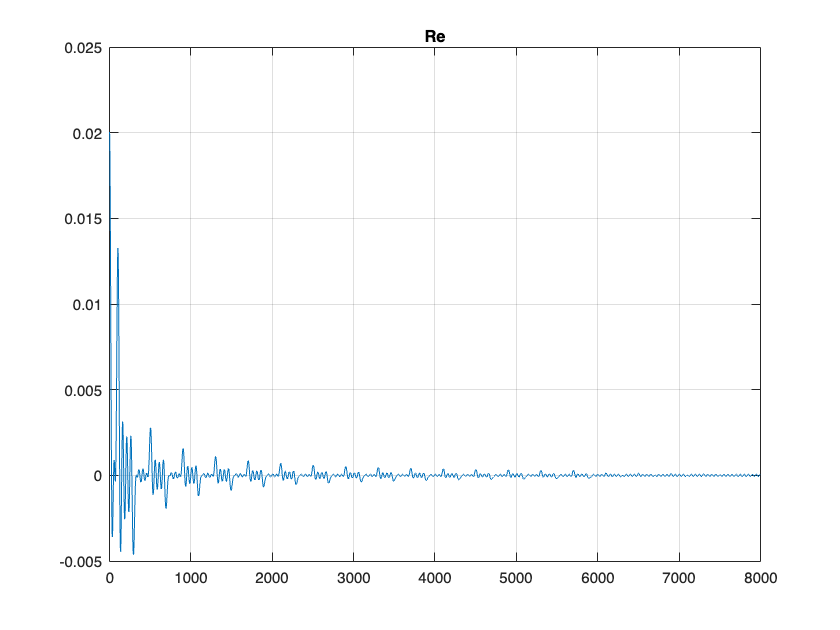


% plot da parte real
figure;
plot(f, real(XN));grid on
title('Re');

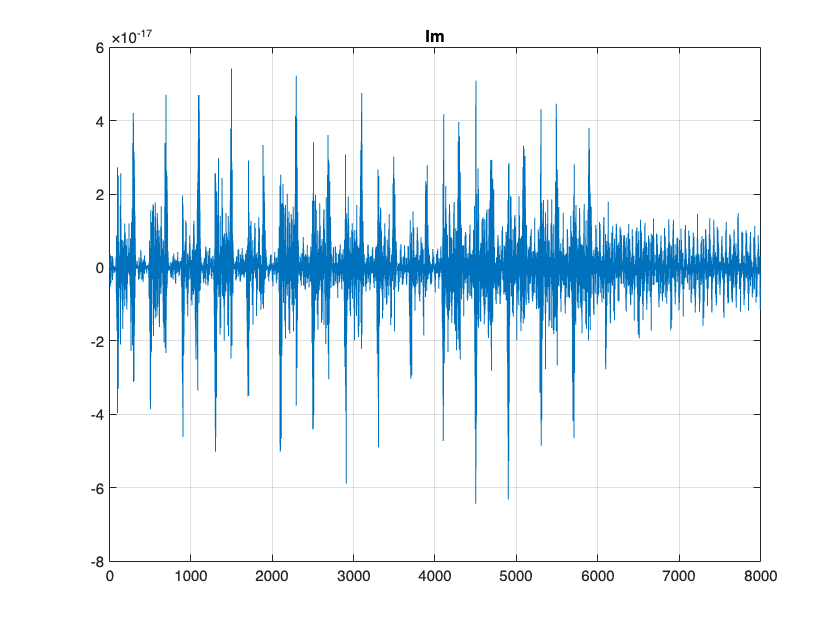


% Plot da parte imaginária
figure;
plot(f, imag(XN));grid on
title('Im');

**Q3.3 **Analisar os espetro de Q3.2